# Finding a 4D SSM for an oscillator chain

This is an example of how to reconstruct a slow 4D SSM of a mechanical system using synthetic measurements of the full state space. In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass.

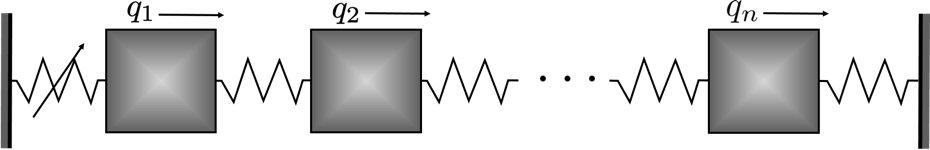

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

n         = 6;      % number of masses
mass      = 1;
stiffness = 1;
damping   = 0.03;

[F, M, C, K, fnl, lambda] = oscillator(n, mass, stiffness, damping);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 2;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories. To this end we pick evenly spaced points in the phase space at a given distance from the origin. Thus all modes will be present at first. We expect the trajectories to eventually converge onto a slow 4D manifold, which will be identified and used to reduce the system dynamics.

ICRadius = 0.2;
IC = ICRadius * pickPointsOnHypersphere(nTraj, 2*n, 1);

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
tEnd = 500;
nSamp = 5000;
dt = tEnd/(nSamp-1);
tic
xData = integrateTrajectories(F, observable, tEnd, nSamp, nTraj, IC);

simulating trajectory 1 of 2...
simulating trajectory 2 of 2...


toc

Elapsed time is 0.132725 seconds.


## Data filtering

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the middle mass displacement. In general, there may be many vibratory modes present at first, but the faster ones quickly die out. 

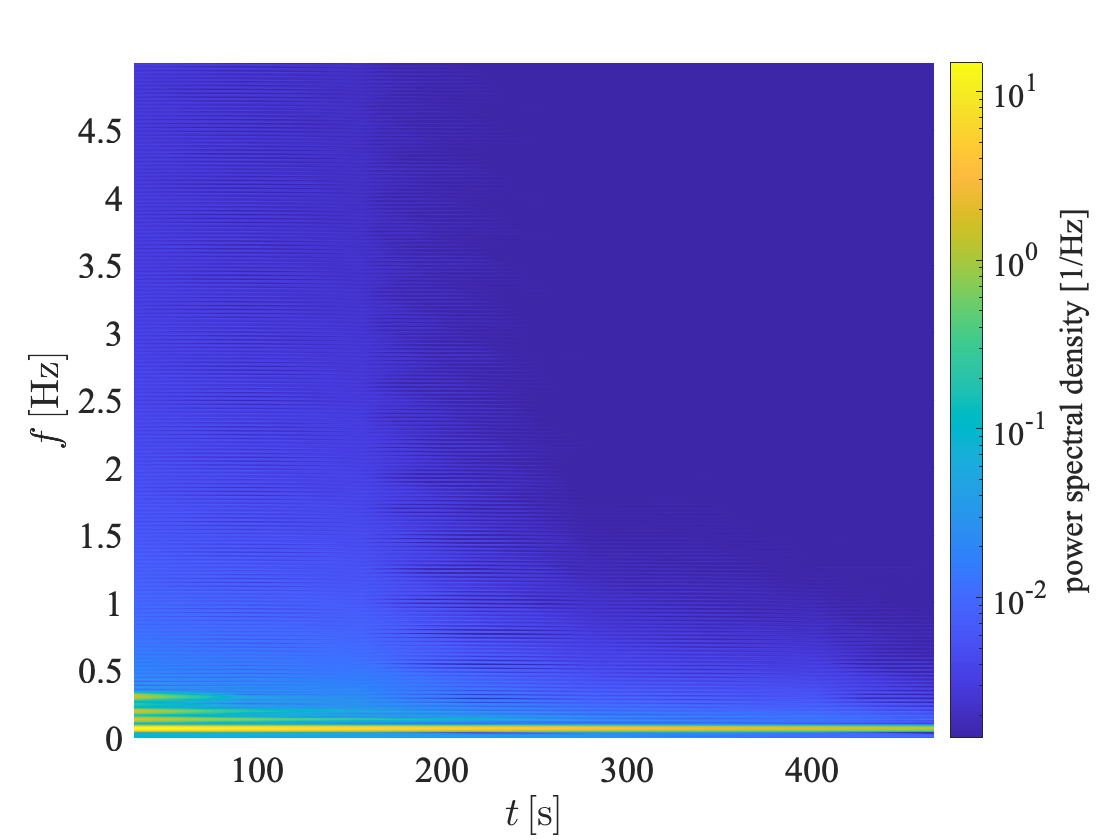

showSpectrogram(xData(indTrain,:), fix(n/2));

Next, we use the information from the spectrogram to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. We keep only the data in the time interval `sliceInt`.

sliceInt = [60, tEnd];
xDataTrunc = sliceTrajectories(xData, sliceInt);
SSMDim = 4;

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

The eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 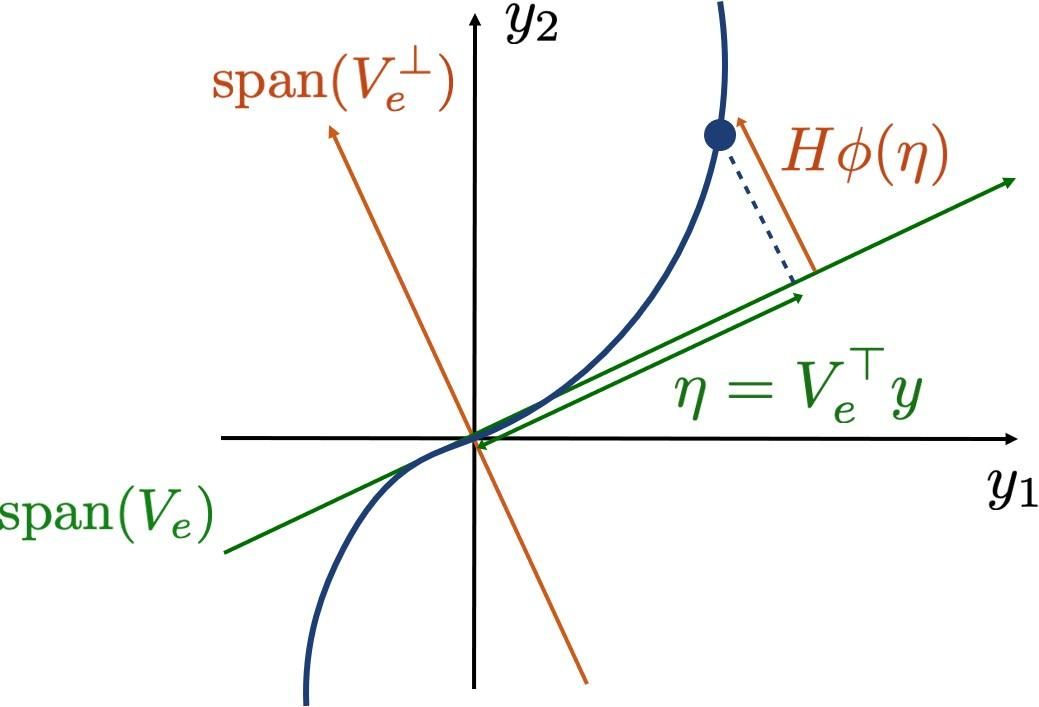

We therefore seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

SSMOrder = 3;
[V, SSMFunction, mfdInfo] = IMparametrization(xDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    4.110593e-08    4.421e-14    1.079e-10

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the plane. 

yData = getProjectedTrajs(xData, V);
yDataTrunc = getProjectedTrajs(xDataTrunc, V);

We plot the test and training set trajectories projected onto the plane. After all initial transients die out, the trajectories seem to be confined to a slowly decaying oscillating eigenmode.

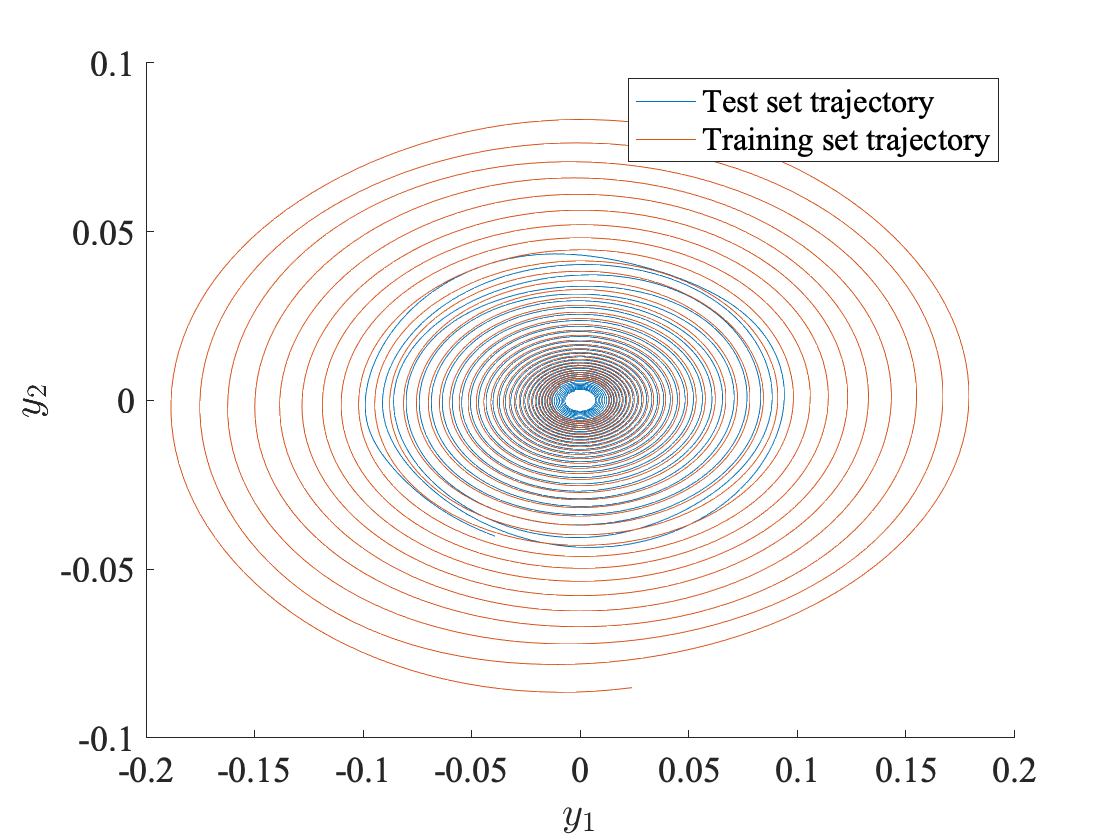

plotReducedCoords(yData);
legend({'Test set trajectory', 'Training set trajectory'})

To visualize convergence onto the slow manifold after vibrations in the modes of larger damping die out, we can plot the trajectories in modal coordinates.

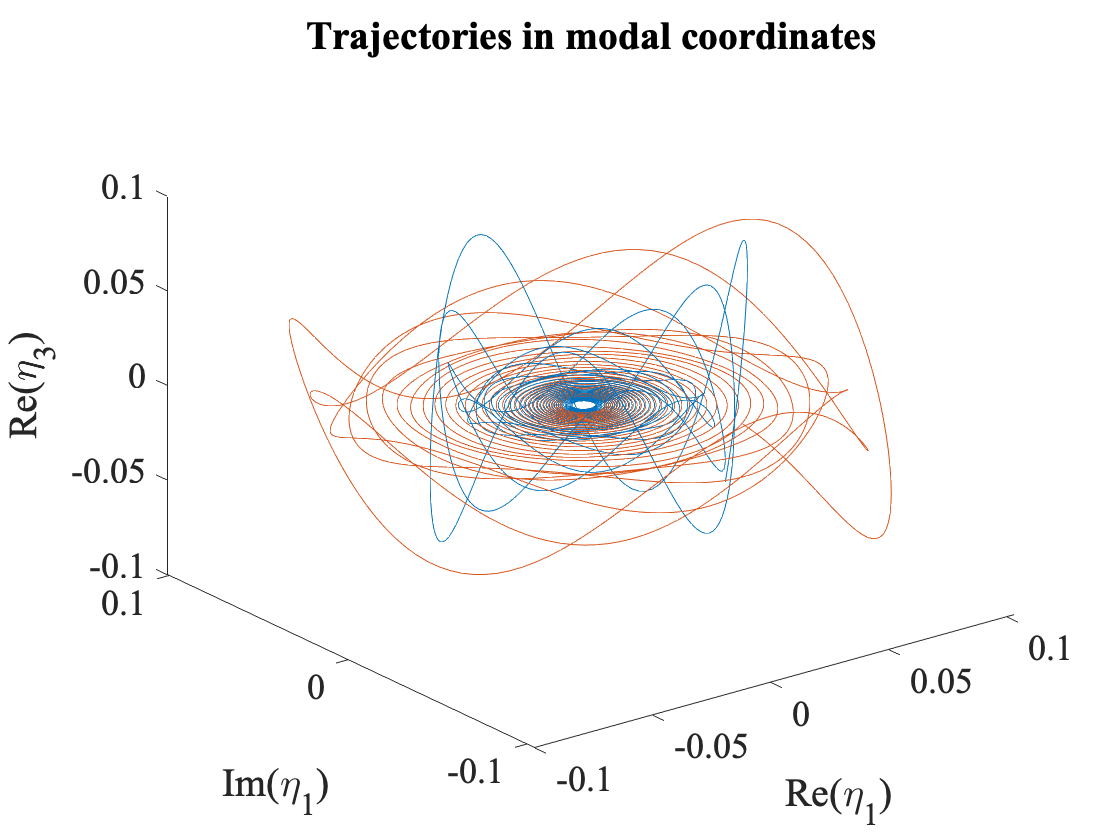

A = [zeros(n), eye(n);
    -M\K,     -M\C];
plotModes = [1,3];
plotModalTrajectories(xData, A, plotModes)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMdynamics_map` fits a polynomial map


$$y_{k+1} = W_r \phi(y_k)$$


where $\phi(y)$ again computes a vector of all monomials of $y$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$z_{k+1} = N(z_k) \approx Dz_k + W_n\phi(z_k)$$


with $D$ a diagonal matrix and $W_n$ containing nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(y) \approx y + W_t \phi(y)$$


[~,Tinv,N,T,NormalFormInfo] = IMdynamics_map(yDataTrunc(indTrain,:), 'R_PolyOrd', 3, 'style', 'normalform');

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      9.34096e-10                      2.65e-07
     1           5      8.62009e-10            820        1.3e-07  
     2           6      7.94556e-10              1       1.23e-07  
     3           7      7.22311e-10              1        1.7e-07  
     4           8      6.87403e-10              1       8.75e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

We transform the initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory. The error RRMSE is computed as the average distance of the predicted trajectory to the actual one in the full state space.

zData = transformComplex(Tinv, yDataTrunc);
[zRec, xRecNormal] = iterateMaps(N, zData, @(q) SSMFunction(T(q)));
yRecNormal = transformComplex(T, zRec);
[reducedTrajDist, fullTrajDist] = computeRecDynErrors(yRecNormal, xRecNormal, yDataTrunc, xDataTrunc);

RRMSE_normal = mean(fullTrajDist(indTest))

RRMSE_normal = 0.0270

## Evaluation of reduced dynamics

We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 

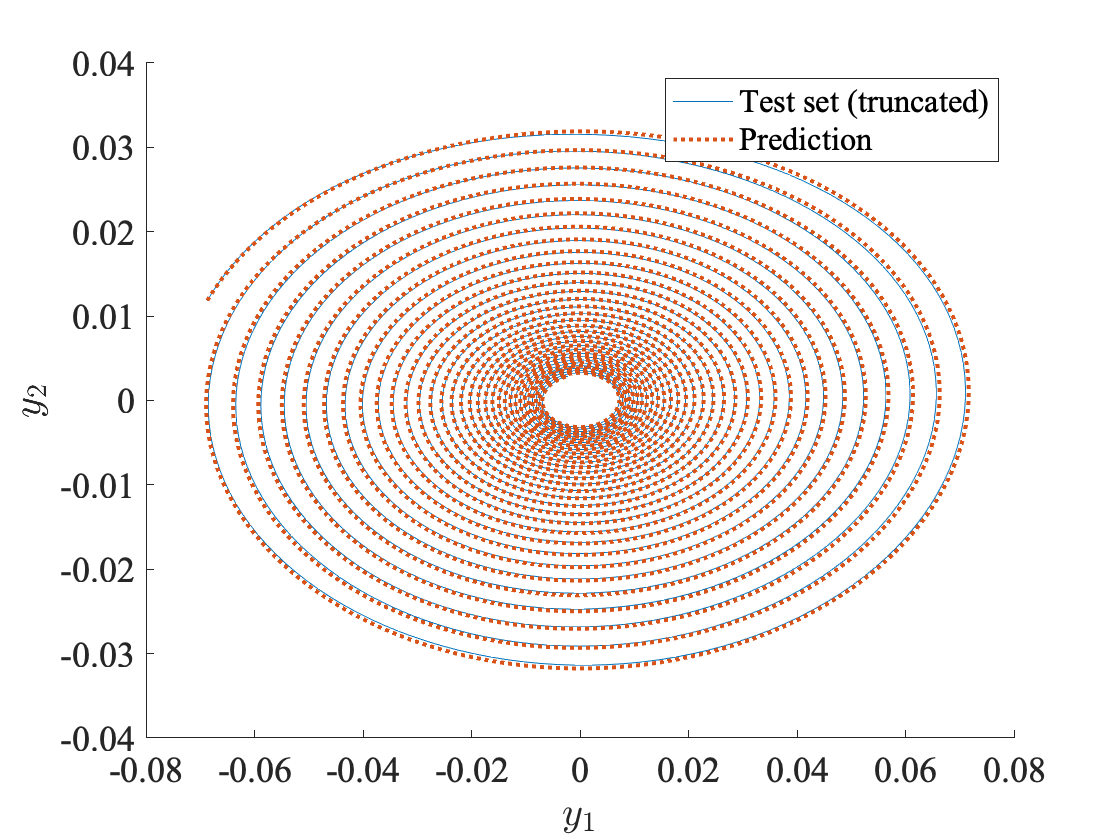

plotReducedCoords(yDataTrunc(indTest(1),:), yRecNormal(indTest(1),:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted displacement for one of the masses. The reduced model seems to do well on previously unseen data, provided that it is initalized close to the 2D manifold.

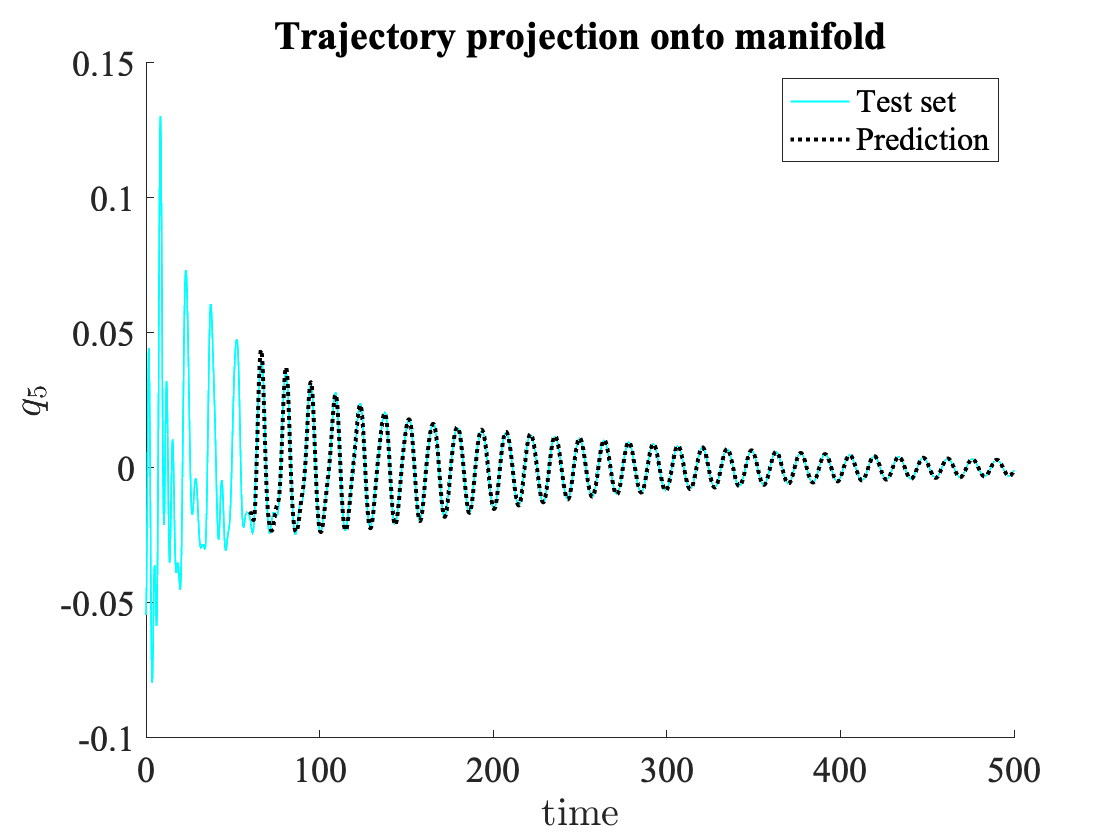

plotReconstructedTrajectory(xData(indTest(1),:), xRecNormal(indTest(1),:), n-1, 'c')
legend({'Test set', 'Prediction'})

Finally we compare the estimated eigenvalues of the continuous evolution function to the ones computed with SSMTool. 

DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues =   -0.0054 - 0.4450i
  -0.0054 + 0.4450i
  -0.0192 - 0.8677i
  -0.0192 + 0.8677i


normalFormEigenvalues = computeEigenvaluesMap(NormalFormInfo, dt)

normalFormEigenvalues =   -0.0054 + 0.4446i
  -0.0054 - 0.4446i
  -0.0209 + 0.8647i
  -0.0209 - 0.8647i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone surfaces for the instantaneous damping and frequency.

N_info = NormalFormInfo.N;
[damp,freq] = nonres_normalform(N_info.coeff,N_info.exponents, dt);

The data-driven polar normal form dynamics reads:

                        1                     r2_1                      r2_2         
                _________________    ______________________    ______________________

    Z_1(r) =    0.99847+0.044427i    4.0531e-05+0.00032652i    6.5186e-06+7.3956e-06i
    Z_2(r) =    0.99418+0.0862i      0.00020501+0.00060341i     6.294e-06+3.083e-05i 

Notation: z_j = r_j*exp(1i*\theta_j) where r_j is the amplitude and \theta_j the phase; rk_j is the k-th power of r_j.
The polar form map consists of r_j <--| |Z_j(r)|r_j and \theta_j <--| \theta_j  + \arg(Z_j(r))


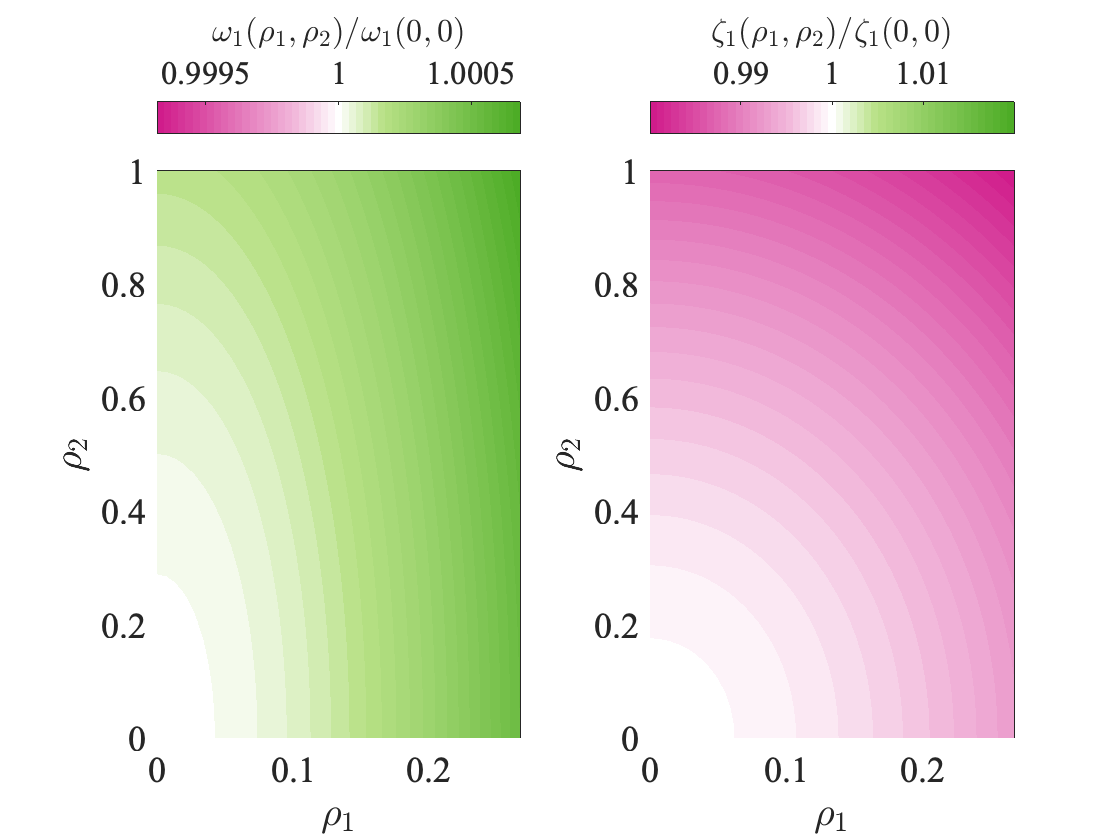

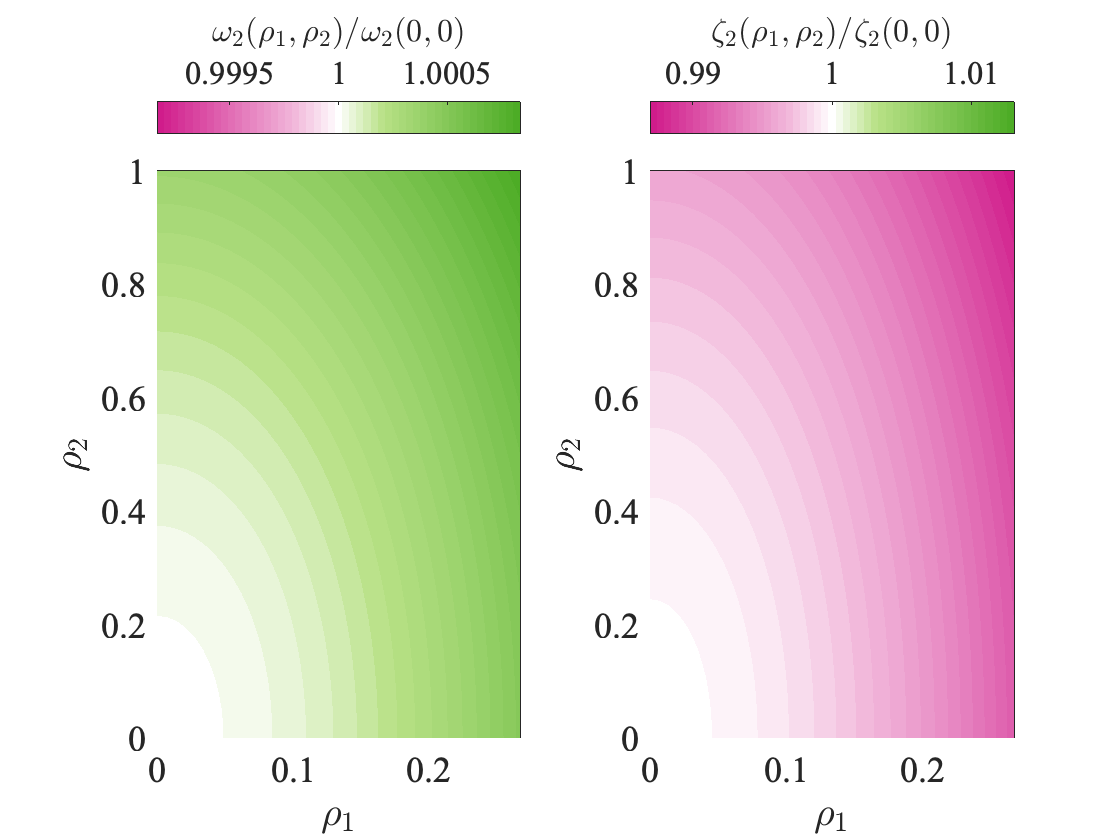

maxRho = abs(zData{indTest(1),2}(1,1));
if SSMDim == 2
    backbonecurves(damp, freq, SSMFunction, T, n-1, maxRho, 'norm');
elseif SSMDim == 4
    backbonesurfaces(damp, freq, [maxRho, 1], 'norm');
end